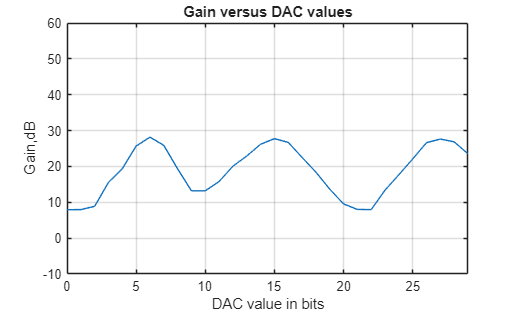

load Gain_characteristic.mat

ATTENUATOR = false;


%voltage gain in dB
if ATTENUATOR
    Gain = 1./Gain
end
gain_in_db = 20*log10(Gain);

f = figure();
plot(GainIndex,gain_in_db)
hold on
grid on
axis tight
ylim([-10,60])
if ATTENUATOR == true
    title("Attenuation versus DAC values")
else
    title("Gain versus DAC values")
end
xlabel("DAC value in bits")
ylabel("Gain,dB")

% axis tight